# XTD_C4: Persistence Model Fitting

% fileDirs = [{'D:\PFC\GE11_Session132'},...
%     {'D:\PFC\GE13_Session083'},...
%     {'D:\PFC\GE14_Session123'},...
%     {'D:\PFC\GE17_Session095'},...
%     {'D:\PFC\GE24_Session096'}];
fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);
nanWmap = rbDivMap;
nanWmap(1,:) = [1,1,1];

## Compile Data Across Rats

prevTrlLat = cell(1,4);
trialLightLat = cell(1,4);
pokeInLat = cell(1,4);
rwdSigLat = cell(1,4);
pokeOutLat = cell(1,4);
rwdLat = cell(1,4);
nxtTrlLat = cell(1,4);
for ani = 1:length(fileDirs)
    aniDta = load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'persTrialFit_Real', 'persIntervalFit_Real',...
        'persTrialFit_ChanceFull', 'persIntervalFit_ChanceFull', 'persTrialFit_ChancePos', 'persIntervalFit_ChancePos');   
    fns = fieldnames(aniDta);
    if ani == 1
        for fn = 1:length(fns)
            eval(sprintf('%s = aniDta.%s;', fns{fn}, fns{fn}));
        end
    else
        for d = 1:numel(persTrialFit_Real)
            for fn = 1:length(fns)
                eval(sprintf('%s{d} = cat(1,%s{d}, aniDta.%s{d});', fns{fn}, fns{fn}, fns{fn}));
            end
        end
    end
    load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'trialInfo', 'mlb');
    cur_TrialInfo = cell2mat(trialInfo(cellfun(@(a)~isempty(a),trialInfo))');
    for pos = 1:mlb.seqLength
        curPosLog = [cur_TrialInfo.Position]==pos;
        if strcmp(mlb.alignments{1}, 'PokeIn')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeInIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
        elseif strcmp(mlb.alignmnents{1}, 'PokeOut')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]*-1];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeOutIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
        end
    end
end


## Plot Things

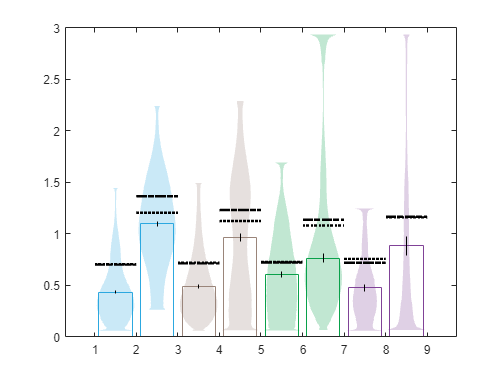

figure; 
for pos = 1:mlb.seqLength
    tempTrialReal = persTrialFit_Real{pos,pos,pos};
    tempTrialChanceF = mean(persTrialFit_ChanceFull{pos,pos,pos});
    tempTrialChanceP = mean(persTrialFit_ChancePos{pos,pos,pos});
    tempIntReal = persIntervalFit_Real{pos,pos,pos};
    tempIntChanceF = mean(persIntervalFit_ChanceFull{pos,pos,pos});
    tempIntChanceP = mean(persIntervalFit_ChancePos{pos,pos,pos});
    mlb.PlotMeanVarViolin(pos*2-0.5, tempTrialReal, 1, 0.05, mlb.PositionColors(pos,:));
    plot(pos*2+[-1 0], repmat(tempTrialChanceF,[1,2]), ':k', 'linewidth', 2);
    plot(pos*2+[-1 0], repmat(tempTrialChanceP,[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pos*2+0.5, tempIntReal, 1, 0.05, mlb.PositionColors(pos,:));
    plot(pos*2+[0 1], repmat(tempIntChanceF,[1,2]), ':k', 'linewidth', 2);
    plot(pos*2+[0 1], repmat(tempIntChanceP,[1,2]), '-.k', 'linewidth', 2);
end

## Stats

1) ANOVAs... 

    --- Position x Epoch... 

        --- Should be main effects of Epoch... 

        --- Position may not show a main effect...

        --- Should observe a significant interaction I think... 

    --- Post-hocs

2) Difference from chance.... The chance vs real effect is a little awkward... specifically that there is an epoch effect for the chance values as well as the real...

--- May need to normalize based on event duration... however when I did that the difference ended up being not significant